This is a scratch file that I am using while I find the right data - see notes TODO

## Summary

The first thing we l consider is if the LumiLEDs in the prototype are bright enough.  

The tongue fluorescence measured at the lowest level of SemiLEDS that we used in the experiments (90 mA for 405 and 80 mA for 415), is above the predicted reflectance, indicating that even at the lowest intensity level we are measuring fluorescence

Unfortunately, the measurements that Krithin and I made of the LumiLEDs with 13 degree reflector are lower than the min levels

In the future, use oeTongueLipRootPath.m

see also notes at the end of this script - reminding me to put SemiLEDs and LumiLEDS measurement data into the oralEye repository, with documentation in comments

%% make sure these libraries are on your path
cd /Users/joyce/Github/isetcam;
addpath(genpath(pwd));
cd /Users/joyce/Github/isetfluorescence;
addpath(genpath(pwd));
cd /users/joyce/Github/oraleye/;
addpath(genpath(pwd));
cd /users/joyce/Github/oe_tongue_lip/;
addpath(genpath(pwd));

ieInit;
wave = 380:4:700;

### Is our excitation light strong enough to excite tissue fluorescence?

One way to answer this question is to measure the intensity of the excitation light and compare it to the intensity of the excitation lights we used in our tongue-lip measurements. 

What is the lowest intensity that excites tissue fluorescence that can be measured with the PR670. We used the SemiLEDs 415 to excite and measure tongue and lip fluorescence.  We can compare the SemiLED 415 light levels that excites tissue fluorescence and compare to the light level that we plan to use in the prototype.

We can also use the spectral quantum efficiency of the proposed camera to calculate the exposure level that we would need in order to measure the tissue fluorescence excited by that light level. 

### Compare tongue fluorescence measured at the lowest level of light intensity to predicted tongue reflectance (for 405 and 415 only)

see oeFigure3a_DataRange.mlx 

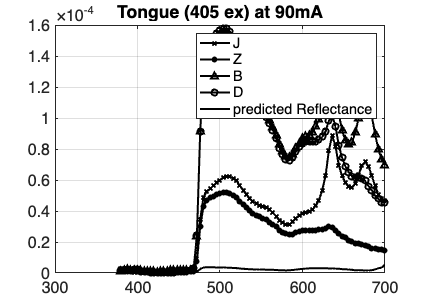

nWave = [];  % 580 

T = oeDatabaseCreate;

T2 = oeDatabaseLightsCreate;
unwanted405 = ieTableGet(T2,'condition','unwantedreflected','ewave',405,'elevel',90);
unwanted415 = ieTableGet(T2,'condition','unwantedreflected','ewave',415,'elevel',80);

tongue = ieReadSpectra('tongue.mat',wave); 
meanTongueReflectance = mean(tongue,2);

data405 = oeReadFiles(unwanted405,'waves',wave);
predicted405= data405.*meanTongueReflectance;

data415 = oeReadFiles(unwanted415,'waves',wave);
predicted415 = data415.*meanTongueReflectance;

symbols = {'kx-','k*-','k^-','ko-'};

tongueFiles405min = ieTableGet(T,'ewave',405,'substrate','tongue','elevel',90,'return','files');
data = oeReadFiles(tongueFiles405min,'waves',wave,'normalized wave',nWave);
ieFigure;
for ii= 1:numel(tongueFiles405min)
    plot(wave,data(:,ii),symbols{ii}); hold on;
end
plot(wave,predicted405,'k','LineWidth',2);
legend('J','Z','B','D','predicted Reflectance');
title('Tongue (405 ex) at 90mA');
grid on;
set(gca,'fontsize',16);

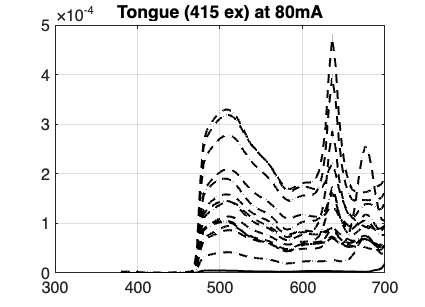


tongueFiles415min = ieTableGet(T,'ewave',415,'substrate','tongue','elevel',80,'return','files');
data = oeReadFiles(tongueFiles415min,'waves',wave,'normalized wave',nWave);
ieFigure;
for ii= 1:numel(tongueFiles415min)
    plot(wave,data(:,ii),'k--'); hold on;
end
plot(wave,predicted415,'k','LineWidth',2);
title('Tongue (415 ex) at 80mA');
grid on;
set(gca,'fontsize',16);

T3 = oeDatabaseLightsCreate;

files405 = ieTableGet(T3,'condition','experiment','ewave',405,'elevel',90);
data405min = oeReadFiles(files405,'waves',wave);

files415 = ieTableGet(T3,'condition','experiment','ewave',415,'elevel',80);
data415min = oeReadFiles(files415,'waves',wave);

ieFigure;
plot(wave,data405min(:,2),'k-','LineWidth',2); hold on;
plot(wave,data415min(:,2),'k--','LineWidth',2);
legend('405 nm at 90 mA','415 nm at 80 mA');


### Compare 

to our (Krithin and Joyce) measurement of the LumiLED 13 degree 

Unfortunately, it is still much lower than the lowest level of the SemiLEDs

cd '/Users/joyce/Library/CloudStorage/GoogleDrive-jefarrel@stanford.edu/My Drive/Projects/Oral Cancer Screening/Spectral Data/Lab Measurements/2025-04-04';

LumiLED1amp = ieReadSpectra('spd-2025-04-04-12_lumiLED5Volts1Amp.mat',wave);
LumiLED2amp = ieReadSpectra('spd-2025-04-04-12_lumiLED5Volts2Amp.mat',wave);
plot(wave,LumiLED1amp,'g','LineWidth',2);
plot(wave,LumiLED2amp,'r','LineWidth',2);
% LumiLED3amp = ieReadSpectra('spd-2025-04-04-12_lumiLED5Volts3Amp.mat',wave);

legend('SemiLED 405 nm at 90 mA','SemiLED 415 nm at 80 mA','LumiLED(13 deg) 1A','LumiLED(13 deg) 2A');
grid on;
set(gca,'fontsize',16);


### Compare 

to the maximum levels of SemiLEDs

files405 = ieTableGet(T3,'condition','experiment','ewave',405,'elevel',980);
data405max = oeReadFiles(files405,'waves',wave);

files415 = ieTableGet(T3,'condition','experiment','ewave',415,'elevel',920);
data415max = oeReadFiles(files415,'waves',wave);

plot(wave,data405max(:,2),'b-','LineWidth',2); hold on;
plot(wave,data415max(:,2),'b--','LineWidth',2);

legend('SemiLED 405 nm at 90 mA','SemiLED 415 nm at 80 mA','LumiLED(13 deg) 1A','LumiLED(13 deg) 2A', ...
  'SemiLED 405 nm at 980 mA', 'SemiLED 415 nm at 920 mA' );

### compare 

 to the measurements of LumiLEDs that Molly made last year

cd '/Users/joyce/Library/CloudStorage/GoogleDrive-jefarrel@stanford.edu/My Drive/Projects/Oral Cancer Screening/Spectral Data/Lab Measurements/Molly Shared/Lights'
LumiLED415_13deg = ieReadSpectra('spd-2024-01-30-LumiLEDs415nm-Rel-wide.mat',wave); % no comment
plot(wave,LumiLED415_13deg,'r--','LineWidth',2);

legend('SemiLED 405 nm at 90 mA','SemiLED 415 nm at 80 mA','LumiLED(13 deg) 1A','LumiLED(13 deg) 2A', ...
  'SemiLED 405 nm at 980 mA', 'SemiLED 415 nm at 920 mA', ...
  'LumiLED415_13deg (Molly');

### compare 

to Velscope

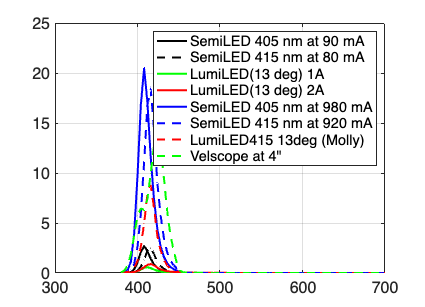

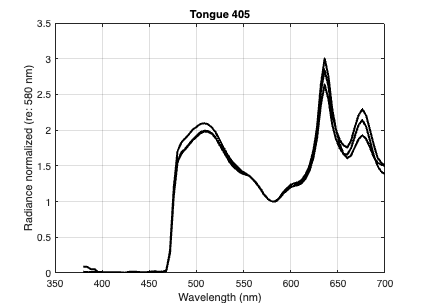


VELscope = ieReadSpectra('spd-2023-09-28-VELscope-4in.mat',wave);
plot(wave,VELscope,'g--','LineWidth',2);
legend('SemiLED 405 nm at 90 mA','SemiLED 415 nm at 80 mA','LumiLED(13 deg) 1A','LumiLED(13 deg) 2A', ...
  'SemiLED 405 nm at 980 mA', 'SemiLED 415 nm at 920 mA', ...
  'LumiLED415 13deg (Molly)','Velscope at 4" ');

## SemiLEDS used in tongue and lip experiments

files405 = ieTableGet(T3,'condition','experiment','ewave',405);
data405 = oeReadFiles(files405,'waves',wave,'normalized wave', []);

files415 = ieTableGet(T3,'condition','experiment','ewave',415);
data415 = oeReadFiles(files415,'waves',wave,'normalized wave', []);

files450 = ieTableGet(T3,'condition','experiment','ewave',450);
data450 = oeReadFiles(files450,'waves',wave,'normalized wave', []);

ieFigure;

for ii=1:size(data405,2)
    hA = plot(wave,data405(:,ii),'k-'); hold on;
end
for ii=1:size(data415,2)
    hB = plot(wave,data415(:,ii),'k--');
end

for ii=1:size(data450,2)
    hC = plot(wave,data450(:,ii),'k:');
end

grid on; xlabel('Wavelength (nm)'); ylabel('Radiance');
title('Spectral energy in the excitation lights at different intensities');

set(gca,'fontsize',16);


set(gca,'LineWidth',2);
ll = findobj(gca,'type','line');
for ii =1:numel(ll)
    set(ll(ii),'lineWidth',2);
end

### Measurements of SemiLEDs made by Krithin and Joyce

cd '/Users/joyce/Library/CloudStorage/GoogleDrive-jefarrel@stanford.edu/My Drive/Projects/Oral Cancer Screening/Spectral Data/Lab Measurements/2025-04-07';
load('spd-2025-04-07-SemiLEDs415-1amp.mat'); plot(wavelength, data,'r','LineWidth',3);
 %{
load('spd-2025-04-07-ProtoType13degLED.mat');
ieFigure; plot(wavelength,data); hold on
load('spd-2025-04-07-SemiLEDs415-1amp-3.mat'); plot(wavelength, data);
load('spd-2025-04-07-SemiLED_4.mat'); plot(wavelength, data);		
load('spd-2025-04-07-SemiLEDs415-1amp-4.mat'); plot(wavelength, data);
load('spd-2025-04-07-SemiLEDs415-1amp-2.mat'); plot(wavelength, data);	
load('spd-2025-04-07-SemiLEDs415-1amp.mat'); plot(wavelength, data);
*}


## TODO

### Move good data to oraleye

add comments about the current driving the lumiLED, imaging distance and the reflector beam angle

%VELscope from 2022, SemiLEDs in 425 spf and 450 spf, OralEye blue light

cd '/Users/joyce/Library/CloudStorage/GoogleDrive-jefarrel@stanford.edu/My Drive/Projects/Oral Cancer Screening/Spectral Data/Lab Measurements/Molly Shared/Lights'
VELscope = ieReadSpectra('spd-2023-09-28-VELscope-4in.mat',wave);
ieFigure; plot(wave,VELscope,'r'); hold on;
%{
what happened to SemiLEDs 405, 415?
SemiLEDs_425 = ieReadSpectra(spd-2023-10-30-SemiLEDswcl-1000mA-4in-425nmSPF.mat');
plot(wavelength,SemiLEDs_425); 
SemiLEDs_450 = ieReadSpectra('spd-2023-10-30-SemiLEDswcl-1000mA-4in-450nmSPF.mat');
plot(wavelength,data); 
%}
% This does not seem right, OralEye was brighter than Velscope?
% could be because the measurement was made in the center of the brightest
% spot on the LumiLED and at 4 inches, the Velscope has a dark spot in the
% middle?
OralEye_Blue = ieReadSpectra('spd-2024-01-12-OralEye-BlueLight-InstOn.mat',wave);
plot(wave,OralEye_Blue,'g'); 
LumiLED415_7deg = ieReadSpectra('spd-2024-01-30-LumiLEDs415nm-Rel-narrow.mat',wave); % comment 4 inches
plot(wave,LumiLED415_7deg,'k'); 
LumiLED415_13deg = ieReadSpectra('spd-2024-01-30-LumiLEDs415nm-Rel-wide.mat',wave); % no comment
plot(wave,LumiLED415_13deg,'k--');
xlim([350 500]);

legend('Velscope', 'OralEye', 'LumiLED415 7 deg', 'LumiLED415 13 deg')
grid on;
set(gca,'fontsize',16);

### To correct later

These data are not correct - how did this happen?

- see data in .../Spectral Data/Lab Measurements/Molly Shared/Lights' (above)

cd '/Users/joyce/Library/CloudStorage/GoogleDrive-jefarrel@stanford.edu/My Drive/Projects/Oral Cancer Screening/Spectral Data/Lab Measurements/Molly Shared/PR670 Spectral Data/2024-01-30'
LumiLEDs_7deg_1 = load('spd-2024-01-30-LumiLEDs415nm-Rel-narrow.mat');comment
ieFigure; plot(wavelength,data); hold on;
LumiLEDs_13deg = load('spd-2024-01-30-LumiLEDs415nm-Rel-wide.mat'); comment
plot(wavelength,data,'k--');
%Lumileds used 1000mA, 2000mA is max

cd '/Users/joyce/Library/CloudStorage/GoogleDrive-jefarrel@stanford.edu/My Drive/Projects/Oral Cancer Screening/Spectral Data/Lab Measurements/Molly Shared/PR670 Spectral Data/2023-12-18'
%%Lumileds with 7deg ref
LumiLEDs_7deg = load('2023-12-18-LumiLEDs-4in-2A-Refl-Spot.mat');
% L7 = trapz(LumiLEDs_7deg.wavelength,LumiLEDs_7deg.data);
% L13 = trapz(LumiLEDs_13deg.wavelength,LumiLEDs_13deg.data);
L7 = max(LumiLEDs_7deg_1.data);
L71 = max(LumiLEDs_7deg.data);
C = L71/L7;
LumiLEDs_13deg.data = C.*LumiLEDs_13deg.data;

% figure,plot(VELscope.wavelength,VELscope.data,'k','LineWidth',2);
% hold on
% % plot(SemiLEDs_425.wavelength,SemiLEDs_425.data,'r','LineWidth',2);
% plot(SemiLEDs_450.wavelength,SemiLEDs_450.data,'g','LineWidth',2);
% plot(OralEye_Blue.wavelength,OralEye_Blue.data,'b','LineWidth',2);
figure,
plot(LumiLEDs_7deg.wavelength,LumiLEDs_7deg.data,'r','LineWidth',2);
hold on
plot(LumiLEDs_13deg.wavelength,LumiLEDs_13deg.data,'r--','LineWidth',2);
legend('LumiLEDs-7deg','LumiLEDs-13deg','Fontsize',20);
% legend('VELscope','SemiLEDs','OralEye','LumiLEDs-7deg','LumiLEDs-13deg','Fontsize',20);
xlabel('wavelength','FontSize',20);
xlim([350 500]);
ylabel('spectral radiance','FontSize',20);
grid on
hold off

### Tissue fluorescence at the lowest intensity setting

### Comparing to the Velscope

Molly measured a LumiLed with peak energy at 415 nm, reflector 13 deg wide beam beam angle, 1000mA , constant current, measured at 4 inches. 

Molly also measured the light in a Velscope at a distance of 4 inches in 2024

The Velscope has ring of very bright 425 nm LEDs, surrounding an eyepiece that has a filter to block the reflected light



% Velscope2021Corrected = ieReadSpectra('Velscope2021Corrected.mat',wave ); % note to self to correct the data
% VelscopeNotCorrected = ieReadSpectra('Velscope.mat',wave );
% ieFigure;
% plot(wave,Lled,'b','LineWidth',2); hold on;
% plot(wave,Velscope,'r','LineWidth',2);
% plot(wave,Velscope2021Corrected,'k--');
% plot(wave,VelscopeNotCorrected,'k');


Krithin and Joyce

cd '/Users/joyce/Library/CloudStorage/GoogleDrive-jefarrel@stanford.edu/My Drive/Projects/Oral Cancer Screening/Spectral Data/Lab Measurements/2025-04-04';

% spd-2025-04-04-10watts.mat		
% spd-2025-04-04-3_t2watts.mat
% spd-2025-04-04-12_12t4-watts.mat	
% spd-2025-04-04-3watts.mat
% spd-2025-04-04-12_t2watts.mat		
% spd-2025-04-04-6-7watts.mat
% spd-2025-04-04-12_t3watts.mat		
% spd-2025-04-04-6_t2watts.mat
% spd-2025-04-04-13-48-31.mat
% spd-2025-04-04-12_lumiLED5Volts1Amp.mat	
% spd-2025-04-04-12_lumiLED5Volts2Amp.mat	
% spd-2025-04-04-12_lumiLED5Volts3Amp.mat

%{
ieFigure;
plot(wave,Lled,'b','LineWidth',2); hold on;
Lled5v1Amp = ieReadSpectra('spd-2025-04-04-12_lumiLED5Volts1Amp.mat',wave);
plot(wave,Lled5v1Amp,'k','LineWidth',2); hold on;
Lled5v2Amp = ieReadSpectra('spd-2025-04-04-12_lumiLED5Volts2Amp.mat',wave);
plot(wave,Lled5v2Amp,'r','LineWidth',2); hold on;
Velscope = ieReadSpectra('Velscope20240131.mat',wave );
plot(wave,Velscope,'r--','LineWidth',2); hold on;
title('LumiLED with 13 deg wide beam angle');
legend('1 Amp measured by MM','1 Amp','2 Amp','Velscope');
grid on;
set(gca,'fontsize',16);
%}


### Exposure and Gain

Analyzing the exposure and gain settings for the images we captured with the Velscope and Google Pixel 4a cameras


% Define the directory containing the image files
directory = '/Users/joyce/Library/CloudStorage/GoogleDrive-jefarrel@stanford.edu/My Drive/Projects/Oral Cancer Screening/Velscope/Velscope Images/Nov9'; % Replace with your directory path

% Search for .dng and .DNG files (case-insensitive)
files = [dir(fullfile(directory, '*.dng')); dir(fullfile(directory, '*.DNG'))];

% Check if there are any valid DNG files in the directory
if isempty(files)
    disp('No .dng or .DNG files found in the specified directory.');
    return;
end

% Loop through each file
for i = 1:length(files)
    % Get the full path of the current file
    filePath = fullfile(files(i).folder, files(i).name);
    
    % Extract metadata using imfinfo
    info = imfinfo(filePath);
    
    % Check if DigitalCamera metadata exists
    if isfield(info, 'DigitalCamera')
        % Extract ISO speed and shutter speed
        isoSpeed = info.DigitalCamera.ISOSpeedRatings;
        shutterSpeed = info.DigitalCamera.ExposureTime;
        
        % Display results
        fprintf('File: %s\n', files(i).name);
        fprintf('ISO Speed: %d\n', isoSpeed);
        fprintf('Shutter Speed: %.6f seconds\n', shutterSpeed);
        fprintf('-----------------------------\n');
    else
        fprintf('File: %s does not contain DigitalCamera metadata.\n', files(i).name);
    end
end

plot the velscope filters

VelscopeFilter = ieReadSpectra('VelscopeFilter.mat',wave);
scaledFilter = VelscopeFilter/max(VelscopeFilter);
figure; plot(wave,scaledFilter,'k','LineWidth',2); hold on;
ax = gca;
ax.FontSize = 16;
grid on; xlabel('Wavelength (nm)'); ylabel('Energy(quanta/nm/sec/sr/m^2');
%% plot to show that the light does not get through the filter
% LightFiltered = scaledLight .* scaledFilter;
% figure; plot(theseWaves,LightFiltered ,'b','LineWidth',2); hold on;
% ax = gca;
% ax.FontSize = 16;
% grid on; xlabel('Wavelength (nm)'); ylabel('Energy(quanta/nm/sec/sr/m^2');

scaledLight = Velscope/max(Velscope);
figure; plot(wave,scaledLight,'b','LineWidth',2); hold on;
plot(wave,scaledFilter,'k','LineWidth',2);
grid on; xlabel('Wavelength (nm)'); ylabel('Energy(quanta/nm/sec/sr/m^2');

plot the Google Pixel4a camera sensors

%% plot the spectral sensitivity of the camera
% scale between 0 and 1 for comparison
GooglePixel4aCamera = ieReadSpectra('p4aCorrected.mat',wave);
scaledCamera = GooglePixel4aCamera/max(GooglePixel4aCamera(:,2));
figure; plot(wave,scaledCamera(:,1),'r','LineWidth',2); hold on;
plot(wave,scaledCamera(:,2),'g','LineWidth',2);
plot(wave,scaledCamera(:,3),'b','LineWidth',2);
ax = gca;
ax.FontSize = 16;
grid on; xlabel('Wavelength (nm)'); ylabel('Energy(quanta/nm/sec/sr/m^2');

FilterCamera = GooglePixel4aCamera .* scaledFilter;

figure; plot(wave,scaledFilter,'k','LineWidth',2); hold on;
plot(wave,GooglePixel4aCamera(:,1)/max(GooglePixel4aCamera(:,2)),'r--','LineWidth',2); hold on;
plot(wave,GooglePixel4aCamera(:,2)/max(GooglePixel4aCamera(:,2)),'g--','LineWidth',2);
plot(wave,GooglePixel4aCamera(:,3)/max(GooglePixel4aCamera(:,2)),'b--','LineWidth',2);
ax = gca;
ax.FontSize = 16;
grid on; xlabel('Wavelength (nm)'); ylabel('Energy(quanta/nm/sec/sr/m^2');


figure; plot(wave,FilterCamera(:,1),'r','LineWidth',2); hold on;
plot(wave,FilterCamera(:,2),'g','LineWidth',2);
plot(wave,FilterCamera(:,3),'b','LineWidth',2);
ax = gca;
ax.FontSize = 16;
grid on; xlabel('Wavelength (nm)'); ylabel('Energy(quanta/nm/sec/sr/m^2');
